## Physics Based Dynamic Modeling

### Steps in Dynamic Modeling

- Identify objective for the simulation

- Draw a schematic diagram, labeling process variables

- List all assumptions

- Determine spatial dependence

- Write dynamic balances (mass, species, energy)

- Other relations (thermo, reactions, geometry, etc.)

- Degrees of freedom, does number of equations = number of unknowns?

- Classify inputs as: FC, Disturbance, MV

- Classify outputs as: States, Controlled Variable

- Simplify balance equations based on assumptions

- Simulate steady state conditions (if possible)

- Simulate the output with an input step

### Example: Filling a Water Tank

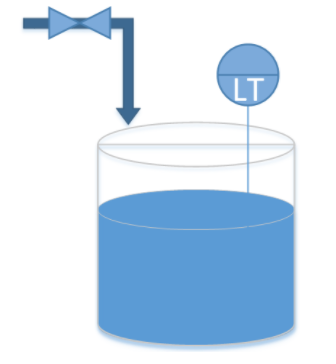

**Balance equation:**


$$\frac{dm}{dt} = \dot{m}_{in} -  \dot{m}_{out} $$


**Assumptions**

- constant water density

- constant cross-sectional area

- linear relation for valve-regulation


$$\rho A \frac{dh}{dt}=cu$$


**Problem**

Simulate the height of a tank by integrating the mass balance equation for a period of 10 seconds. The valve opens to 100% at time=2 and shuts at time=7. Use a value of *1000 kg/m3* for density and *1.0 m2* for the cross-sectional area of the tank. For the valve, assume a valve coefficient of *c=50.0 (kg/s / %open)*.

% clear from previous work
clc;clear all; close all;

% initialize storage vectors
u = zeros(11,1,'double'); % valve status

u =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


u(2:7) = 100;

u =      0
   100
   100
   100
   100
   100
   100
     0
     0
     0


hSim = zeros(11,1,'double'); % simulated height

hSim =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


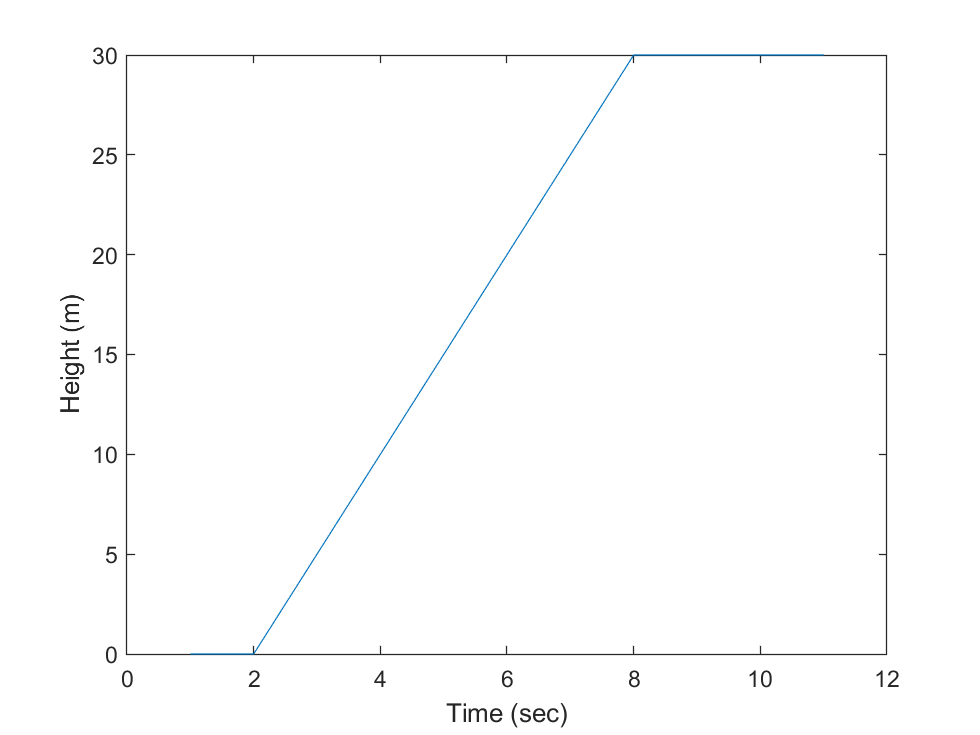


% loop through simulation
for i = 1:10
    [t, h] = ode45(@(t, h) simulate_tank(t, h, u(i)), [0, 1], hSim(i));
    hSim(i+1) = h(end);
end

% plot
plot(hSim)
xlabel('Time (sec)')
ylabel('Height (m)')

function dhdt = simulate_tank(t, h, u)
    rho = 1000;  % density (kg/m^3)
    c = 50;  % valve coefficient (kg/% open)
    A = 1.0;  % Cross sectional area (m^2)
    dhdt = (c*u) / (rho * A);
end